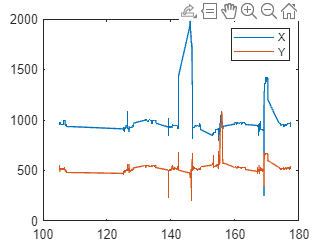

close all;
clear all;
clc;

load('gaze.mat');

Xs_gaze = Xs_gaze/1000000;

% plot(Xs_gaze,GazeX);

GazeX = fillmissing(GazeX,"movmean",20);
GazeY = fillmissing(GazeY,"movmean",20);

plot(Xs_gaze,GazeX);
hold on;
plot(Xs_gaze,GazeY);
hold off;
legend("X","Y");